## Reflectance and Fluorescence of one lesion reported by deVeld et al 2005

De Veld, D. C., Skurichina, M., Witjes, M. J., Duin, R. P., Sterenborg, H. J., & Roodenburg, J. L. (2005). Autofluorescence and diffuse reflectance spectroscopy for oral oncology. *Lasers in Surgery and Medicine: The Official Journal of the American Society for Laser Medicine and Surgery*, *36*(5), 356-364.

Reflectance and fluorescence measuremnts were made sequentially using a probe placed directly on the tissue, illuminating with light, and measuring with an "optical multichannel analyzer" which they referred to as a spectrograph, with no manufacturer specified

Reflectance measurements were made using a Xenon lamp for illumination

Excitation lights were created by placing filters in front of a Xenon lamp : 365, 385, 405, 425, 435, and 450 with <15 nm full-width half-max 

A 460 long pass filter was placed in front of a CCD detector in the "multichannel analyzer" (see Figure 1)

The data in Figure 2 are from one single lesion  but meant to be representative of lesions that were on oral mucosal tissue (They excluded data from the dorsal surface of the tongue and the vermilion border of the lip because these were not similar to the other measurements)

The measured in the center of a lesion, border, surrounding and  "the supposedly healthy tissue at the contralateral position".

## Summary

I don't think we learn much from this paper, however interesting to note that they excluded data from dorsal surface of tongue and vermilion border of lip because they were so significantly different from other tissue fluorescence

The attenuation of fluorescence by reflectance is a strange way to correct for blood absorbance, but their paper does make the point that isolating effects of blood absorbance is important

They report that  the "545-nm dip is less pronounced", and have a strange explanation

## Reflectance

de Veld et al measured reflectance of oral mucosal tissue (not dorsal surface of tongue)

It does not look that different from our measurements of reflectance from the dorsal surface of the tongue, except that, as expected, reflectance is higher from the dorsal surface of the tongue 

This may be due to keratin on the dorsal surface which has low absorbance (and hence, also low fluorescence?) so it reflects light.  Keratin may increase light scatter, and surface of the tongue also increases light scatter.   But, we see that light scatter is low compared to our fluorescence measurements. So, why is there is difference between fluorescence measured on the tongue and in the oral mucosal tissue on the lower lip?  Can we simply explain by less light scatter and light absorbance of excitation light is more effective?

Nonetheless, you can see the effect of light absorbance by oxygenated blood, as you see in all tissue

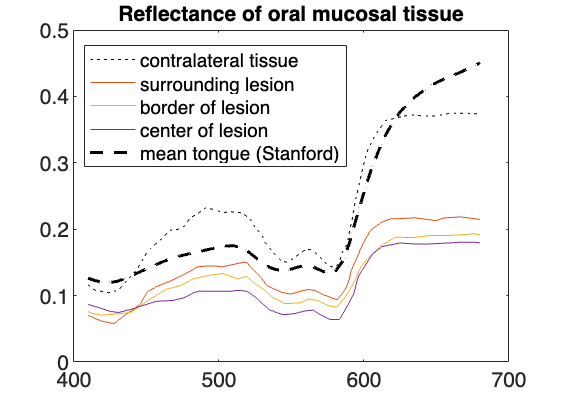

wave = 410:680;
RC = ieReadSpectra('Reflectance_Contralateral.mat',wave);
RS = ieReadSpectra('Reflectance_Surrounding.mat',wave);
RB = ieReadSpectra('Reflectance_Border.mat',wave);
RL = ieReadSpectra('Reflectance_Center.mat',wave);

tongue = ieReadSpectra('tongue.mat',wave); 
meanTongueReflectance = mean(tongue,2);  

ieNewGraphWin; 
plot(wave,RC,'k:'); hold on; % contralateral
plot(wave,RS); hold on;
plot(wave,RB);
plot(wave,RL);
plot(wave,meanTongueReflectance,'k--','LineWidth',2);
title('Reflectance of oral mucosal tissue');
legend('contralateral tissue','surrounding lesion','border of lesion','center of lesion','mean tongue (Stanford)');
fontsize(gca,14,"pixels");


%{
% Normalize by dividing by amplitude at 580
ieNewGraphWin; title('Reflectance normalized at 580')
plot(wave,RC/RC(171),'k:','LineWidth',2); hold on; % contralateral
plot(wave,RS/RS(171),'b','LineWidth',2); hold on;
plot(wave,RB/RB(171),'g','LineWidth',2);
plot(wave,RL/RL(171),'r','LineWidth',2);
plot(wave,meanTongueReflectance/meanTongueReflectance(171),'k--','LineWidth',2);
legend('contralateral tissue','surrounding lesion','border of lesion','center of lesion','mean tongue (Stanford)');
fontsize(gca,14,"pixels");
%}

%{
% Normalize by dividing by max
ieNewGraphWin; 
plot(wave,RC/max(RC(:)),'k:','LineWidth',2); hold on; % contralateral
plot(wave,RS/max(RS(:)),'b','LineWidth',2); hold on;
plot(wave,RB/max(RB(:)),'g','LineWidth',2);
plot(wave,RL/max(RL(:)),'r','LineWidth',2);
title('Reflectance normalized by max');
legend('contralateral tissue','surrounding lesion','border of lesion','center of lesion','mean tongue (Stanford)');
fontsize(gca,14,"pixels");
%}


## Fluorescence

The data for the center. border and surrounding tissue are scaled versions of one another. the data from the "contralateral" side are similar, but but the max is slightly shifted.  NOTE: this is for ONE LESION ONLY. 

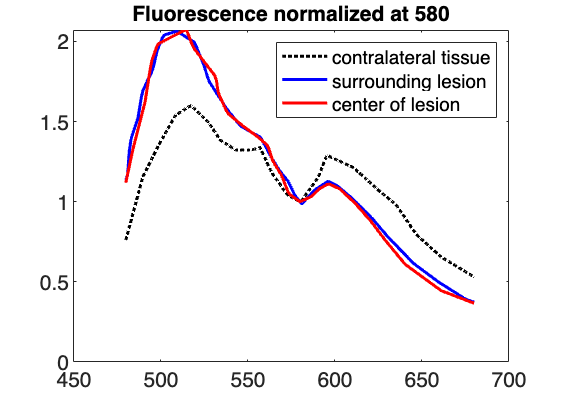

wave = 480:680;
FC = ieReadSpectra('Fluorescence_Contralateral.mat',wave);
FS = ieReadSpectra('Fluorescence_Surrounding.mat',wave);
FL = ieReadSpectra('Fluorescence_Center.mat',wave);

% Normalize by dividing by amplitude at 580
ieNewGraphWin; 
plot(wave,FC/FC(101),'k:','LineWidth',2); hold on;
plot(wave,FS/FS(101),'b','LineWidth',2);
plot(wave,FL/FL(101),'r','LineWidth',2);
title('Fluorescence normalized at 580');
legend('contralateral tissue','surrounding lesion','center of lesion');
fontsize(gca,14,"pixels");




%{
% Normalize by dividing by max
ieNewGraphWin; 
plot(wave,FC/max(FC(:)),'k:','LineWidth',2); hold on; % contralateral
plot(wave,FS/max(FS(:)),'b','LineWidth',2); 
plot(wave,FL/max(FL(:)),'r','LineWidth',2); 
title('Fluorescence normalized by max');
legend('contralateral tissue','surrounding lesion','center of lesion');
fontsize(gca,14,"pixels");
%}

## Corrected fluorescence 

The authors "corrected" for blood absorption by "dividing autofluorescence spectra by diffuse reflectance to a variable power" to remove the peaks at 540 and 580

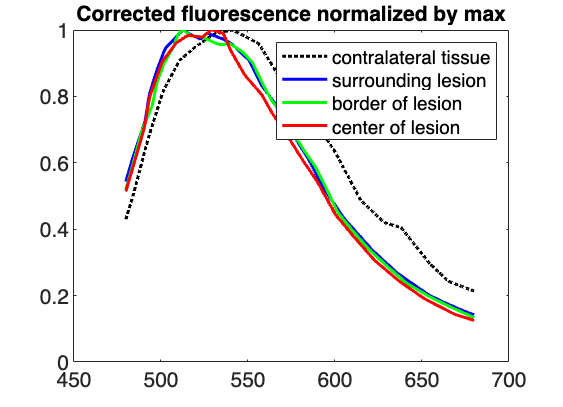

wave = 480:680;
FCC = ieReadSpectra('Fluorescence_Contralateral_Corrected.mat',wave);
FSC = ieReadSpectra('Fluorescence_Surrounding_Corrected.mat',wave);
FBC = ieReadSpectra('Fluorescence_Border_Corrected.mat',wave);
FLC = ieReadSpectra('Fluorescence_Center_Corrected.mat',wave);

%{
% Normalize by dividing by amplitude at 580
ieNewGraphWin; 
plot(wave,FCC/FCC(101),'k:','LineWidth',2); hold on; hold on;
plot(wave,FSC/FSC(101),'b','LineWidth',2);
plot(wave,FBC/FBC(101),'g','LineWidth',2);
plot(wave,FLC/FLC(101),'r','LineWidth',2);
title('Corrected fluorescence normalized at 580');
legend('contralateral','surrounding','border','center');
fontsize(gca,16,"pixels");
%}

% Normalize by dividing by max
ieNewGraphWin; 
plot(wave,FCC/max(FCC(:)),'k:','LineWidth',2); hold on; % contralateral
plot(wave,FSC/max(FSC(:)),'b','LineWidth',2);
plot(wave,FBC/max(FBC(:)),'g','LineWidth',2);
plot(wave,FLC/max(FLC(:)),'r','LineWidth',2);
title('Corrected fluorescence normalized by max');
legend('contralateral tissue','surrounding lesion','border of lesion','center of lesion');
fontsize(gca,14,"pixels");